% Please adjust the path below, if needed
imageFolder = './images/mel';
datasetFolder = fullfile(imageFolder);


imds = imageDatastore(datasetFolder,'IncludeSubfolders',true);

augmenter = imageDataAugmenter('RandXReflection',true);
augimds = augmentedImageDatastore([64 64],imds,'DataAugmentation',augmenter); % [64 64]




filterSize = 5; % 5
numFilters = 64; % 64
numLatentInputs = 100; %100

projectionSize = [4 4 512]; % 512

layersGenerator = [
    featureInputLayer(numLatentInputs)
    projectAndReshapeLayer(projectionSize,numLatentInputs)
    transposedConv2dLayer(filterSize,4*numFilters)
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer(filterSize,2*numFilters,Stride=2,Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer(filterSize,numFilters,Stride=2,Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer(filterSize,3,Stride=2,Cropping="same")
    tanhLayer];

% analyzeNetwork(layersGenerator,TargetUsage="dlnetwork")

disp(layersGenerator)

  13×1 Layer array with layers:

     1   ''   Feature Input            100 features
     2   ''   Project and Reshape      Project and reshape layer with output size 4 4 512
     3   ''   Transposed Convolution   256 5×5 transposed convolutions with stride [1  1] and cropping [0  0  0  0]
     4   ''   Batch Normalization      Batch normalization
     5   ''   ReLU                     ReLU
     6   ''   Transposed Convolution   128 5×5 transposed convolutions with stride [2  2] and cropping 'same'
     7   ''   Batch Normalization      Batch normalization
     8   ''   ReLU                     ReLU
     9   ''   Transposed Convolution   64 5×5 transposed convolutions with stride [2  2] and cropping 'same'
    10   ''   Batch Normalization      Batch normalization
    11   ''   ReLU                     ReLU
    12   ''   Transposed Convolution   3 5×5 transposed convolutions with stride [2  2] and cropping 'sa


lgraphGenerator = layerGraph(layersGenerator);
disp(lgraphGenerator)

  LayerGraph with properties:

         Layers: [13×1 nnet.cnn.layer.Layer]
    Connections: [12×2 table]
     InputNames: {'input'}
    OutputNames: {1×0 cell}



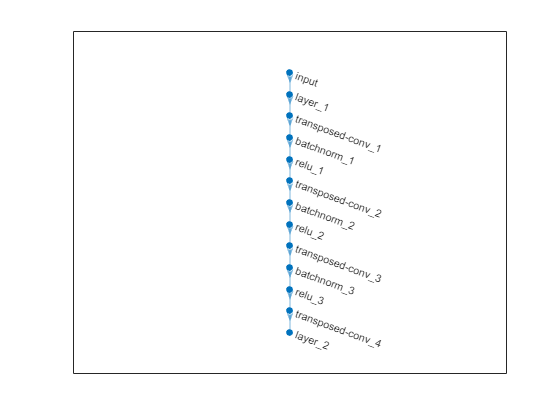

figure
plot(lgraphGenerator)

dlnetGenerator = dlnetwork(lgraphGenerator);

dropoutProb = 0.5;
numFilters = 64; % 64
scale = 0.2;

inputSize = [64 64 3]; % 64
filterSize = 5; % 5

layersDiscriminator = [
    imageInputLayer(inputSize,'Normalization','none','Name','in')
    dropoutLayer(dropoutProb,'Name','dropout')
    convolution2dLayer(filterSize,numFilters,'Stride',2,'Padding','same','Name','conv1')
    leakyReluLayer(scale,'Name','lrelu1')
    convolution2dLayer(filterSize,2*numFilters,'Stride',2,'Padding','same','Name','conv2')
    batchNormalizationLayer('Name','bn2')
    leakyReluLayer(scale,'Name','lrelu2')
    convolution2dLayer(filterSize,4*numFilters,'Stride',2,'Padding','same','Name','conv3')
    batchNormalizationLayer('Name','bn3')
    leakyReluLayer(scale,'Name','lrelu3')
    convolution2dLayer(filterSize,8*numFilters,'Stride',2,'Padding','same','Name','conv4')
    batchNormalizationLayer('Name','bn4')
    leakyReluLayer(scale,'Name','lrelu4')
    convolution2dLayer(4,1,'Name','conv5')];

lgraphDiscriminator = layerGraph(layersDiscriminator);
dlnetDiscriminator = dlnetwork(lgraphDiscriminator);


numEpochs = 800; % 600  800 
miniBatchSize = 128; % 128 256  16
learnRate = 0.00002;% added a 0
gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;
flipFactor = 0.3;
validationFrequency = 100;

augimds.MiniBatchSize = miniBatchSize;


gpuDeviceCount("available")

ans = 1

gpuDeviceTable

ans = 1×5 table
    Index                Name                 ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _____________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce GTX 1060 6GB"          "6.1"               true              true      


gpuDevice

ans =   CUDADevice with properties:

                      Name: 'NVIDIA GeForce GTX 1060 6GB'
                     Index: 1
         ComputeCapability: '6.1'
            SupportsDouble: 1
             DriverVersion: 11.6000
            ToolkitVersion: 11
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 6.4421e+09
           AvailableMemory: 5.0821e+09
       MultiprocessorCount: 10
              ClockRateKHz: 1759000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1


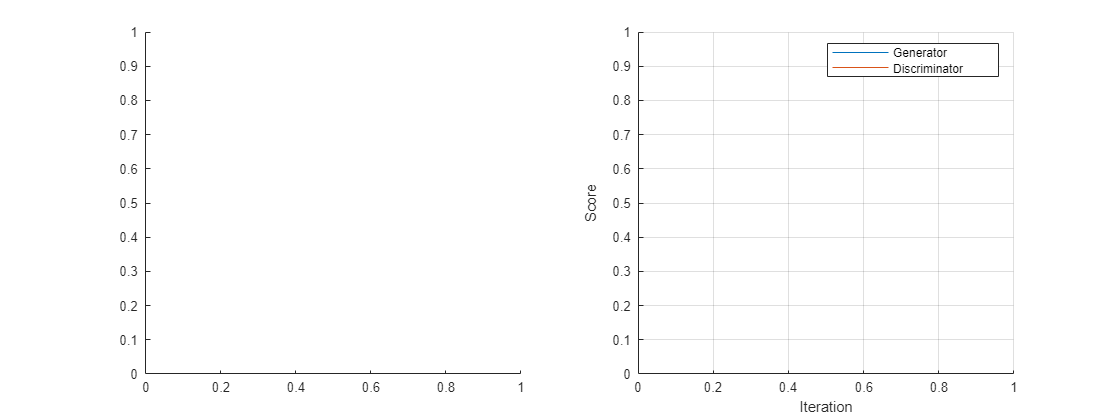


executionEnvironment = "gpu"; % auto

mbq = minibatchqueue(augimds,...
    'MiniBatchSize',miniBatchSize,...
    'PartialMiniBatch','discard',...
    'MiniBatchFcn', @preprocessMiniBatch,...
    'MiniBatchFormat','SSCB',...
    'OutputEnvironment',executionEnvironment);


trailingAvgGenerator = [];
trailingAvgSqGenerator = [];
trailingAvgDiscriminator = [];
trailingAvgSqDiscriminator = [];

numValidationImages = 25;
ZValidation = randn(numLatentInputs,numValidationImages,'single');

dlZValidation = dlarray(ZValidation,'CB');

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZValidation = gpuArray(dlZValidation);
end


f = figure;
f.Position(3) = 2*f.Position(3);

imageAxes = subplot(1,2,1);
scoreAxes = subplot(1,2,2);

lineScoreGenerator = animatedline(scoreAxes,'Color',[0 0.447 0.741]);
lineScoreDiscriminator = animatedline(scoreAxes, 'Color', [0.85 0.325 0.098]);
legend('Generator','Discriminator');
ylim([0 1])
xlabel("Iteration")
ylabel("Score")
grid on

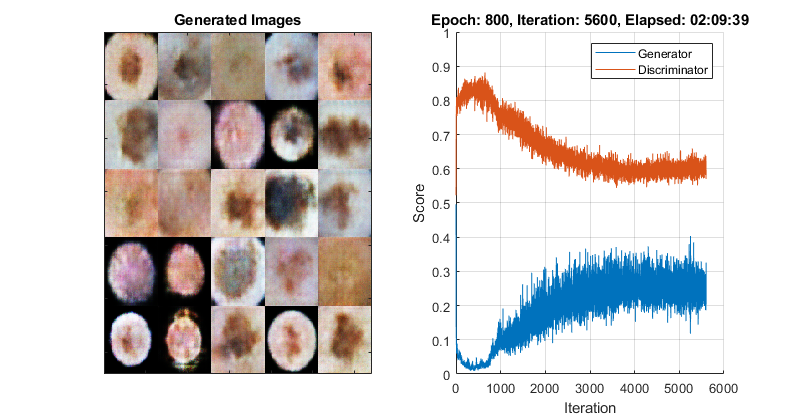

iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs
    
    % Reset and shuffle datastore.
    shuffle(mbq);
    
    % Loop over mini-batches.
    while hasdata(mbq)
        iteration = iteration + 1;
        
        % Read mini-batch of data.
        dlX = next(mbq);
        
        % Generate latent inputs for the generator network. Convert to
        % dlarray and specify the dimension labels 'CB' (channel, batch).
        % If training on a GPU, then convert latent inputs to gpuArray.
        Z = randn(numLatentInputs,miniBatchSize,'single');
        dlZ = dlarray(Z,'CB');        
        
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlZ = gpuArray(dlZ);
        end
        
        
        % Evaluate the model gradients and the generator state using
        % dlfeval and the modelGradients function listed at the end of the
        % example.
        [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator] = ...
            dlfeval(@modelGradients, dlnetGenerator, dlnetDiscriminator, dlX, dlZ, flipFactor);
        dlnetGenerator.State = stateGenerator;
        
        % Update the discriminator network parameters.
        [dlnetDiscriminator,trailingAvgDiscriminator,trailingAvgSqDiscriminator] = ...
            adamupdate(dlnetDiscriminator, gradientsDiscriminator, ...
            trailingAvgDiscriminator, trailingAvgSqDiscriminator, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
        
        % Update the generator network parameters.
        [dlnetGenerator,trailingAvgGenerator,trailingAvgSqGenerator] = ...
            adamupdate(dlnetGenerator, gradientsGenerator, ...
            trailingAvgGenerator, trailingAvgSqGenerator, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
        
        % Every validationFrequency iterations, display batch of generated images using the
        % held-out generator input.
        if mod(iteration,validationFrequency) == 0 || iteration == 1
            % Generate images using the held-out generator input.
            dlXGeneratedValidation = predict(dlnetGenerator,dlZValidation);
            
            % Tile and rescale the images in the range [0 1].
            I = imtile(extractdata(dlXGeneratedValidation));
            I = rescale(I);
            
            % Display the images.
            subplot(1,2,1);
            image(imageAxes,I)
            xticklabels([]);
            yticklabels([]);
            title("Generated Images");
        end
        
        % Update the scores plot.
        subplot(1,2,2)
        addpoints(lineScoreGenerator,iteration,...
            double(gather(extractdata(scoreGenerator))));
        
        addpoints(lineScoreDiscriminator,iteration,...
            double(gather(extractdata(scoreDiscriminator))));
        
        % Update the title with training progress information.
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        title(...
            "Epoch: " + epoch + ", " + ...
            "Iteration: " + iteration + ", " + ...
            "Elapsed: " + string(D))
        
        drawnow
    end
end

Save_GAN_5_64b_600e = dlnetGenerator;
save Save_GAN_5_128b_800e;



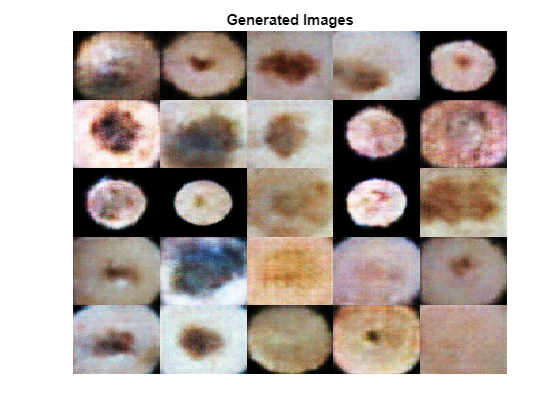



numObservations = 25;
ZNew = randn(numLatentInputs,numObservations,'single');
dlZNew = dlarray(ZNew,'CB');

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZNew = gpuArray(dlZNew);
end


dlXGeneratedNew = predict(dlnetGenerator,dlZNew);

I = imtile(extractdata(dlXGeneratedNew));
I = rescale(I);
figure
image(I)
axis off
title("Generated Images")

## Auxiliary functions

function [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator] = ...
    modelGradients(dlnetGenerator, dlnetDiscriminator, dlX, dlZ, flipFactor)

% Calculate the predictions for real data with the discriminator network.
dlYPred = forward(dlnetDiscriminator, dlX);

% Calculate the predictions for generated data with the discriminator network.
[dlXGenerated,stateGenerator] = forward(dlnetGenerator,dlZ);
dlYPredGenerated = forward(dlnetDiscriminator, dlXGenerated);

% Convert the discriminator outputs to probabilities.
probGenerated = sigmoid(dlYPredGenerated);
probReal = sigmoid(dlYPred);

% Calculate the score of the discriminator.
scoreDiscriminator = (mean(probReal) + mean(1-probGenerated)) / 2;

% Calculate the score of the generator.
scoreGenerator = mean(probGenerated);

% Randomly flip a fraction of the labels of the real images.
numObservations = size(probReal,4);
idx = randperm(numObservations,floor(flipFactor * numObservations));

% Flip the labels.
probReal(:,:,:,idx) = 1 - probReal(:,:,:,idx);

% Calculate the GAN loss.
[lossGenerator, lossDiscriminator] = ganLoss(probReal,probGenerated);

% For each network, calculate the gradients with respect to the loss.
gradientsGenerator = dlgradient(lossGenerator, dlnetGenerator.Learnables,'RetainData',true);
gradientsDiscriminator = dlgradient(lossDiscriminator, dlnetDiscriminator.Learnables);

end

function [lossGenerator, lossDiscriminator] = ganLoss(probReal,probGenerated)

% Calculate the loss for the discriminator network.
lossDiscriminator = -mean(log(probReal)) - mean(log(1-probGenerated));

% Calculate the loss for the generator network.
lossGenerator = -mean(log(probGenerated));

end

function X = preprocessMiniBatch(data)

% Concatenate mini-batch
X = cat(4,data{:});

% Rescale the images in the range [-1 1].
X = rescale(X,-1,1,'InputMin',0,'InputMax',255);

end